# `stft`

短時間フーリエ変換による時間周波数解析

## 構文

## 説明

`s = stft(waveform,timevec) はtimevecを時間軸にもつ時間信号waveformの短時間フーリエ変換(STFT)を返します．`

`s = stft(waveform,timevec,windowWidth) は窓関数幅を指定して短時間フーリエ変換を行います．窓関数幅を大きくすると周波数解像度を上げることができ，小さくすると時間解像度を上げることができます．重要なパラメータのため，必ず指定することをおすすめしますが，指定しない場合，stft関数は窓関数幅を全時間軸の幅の1/100に設定します．`

`s = stft(waveform,timevec,windowWidth,maxF) は最大周波数を指定して短時間フーリエ変換を行います．指定しない場合，解析時間が非常に長くなったり， 目的の周波数範囲を拡大した際に荒い結果になる可能性があります．`

`s = stft( ___,Name=Value) は，名前と値の引数を使用して追加オプションを指定します．オプションにはウィンドウの形状を指定したり，生成されるstft結果の時間・周波数刻み等が含まれます．`

`[s,f,t] = stft( ___ )　はSTFTの結果の周波数軸，時間軸を返します．size(s) =[numel(t),numel(f)]になります．`

`出力引数を設定せずにstft( ___ )を使用すると，現在のFigureウィンドウに， 変換前の時間波形とSTFTの結果を並べて表示します．この方法は，STFTの結果を最初に確認するのに向いています． `

## 例

stft_example.mも参照ください．

### 短時間フーリエ変換による時間周波数解析

波形を読み込みます．時間軸を`timevecとする波形waveform`を処理対象とします．

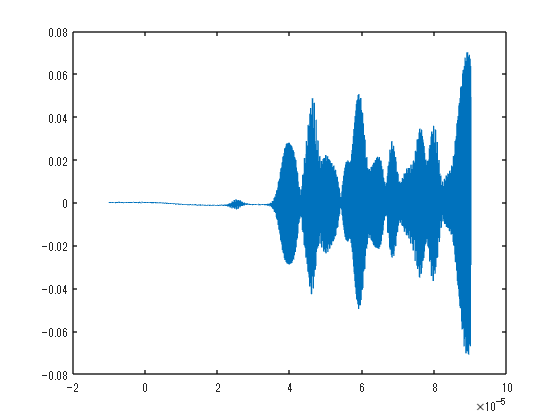

load('test_data\data20231127-113905-trimed.mat'); %timevec
waveform = waveform1and2;
plot(timevec,waveform)

時間幅を2 μsとした窓関数によって短時間フーリエ変換を行います．

windowWidth = 2e-6;
maxF = 15e6;
[s, f, t] = common.stft(waveform, timevec, windowWidth, maxF);

時間軸`tと周波数軸f`を持つ行列`s`を`mesh`プロットによってプロットします．

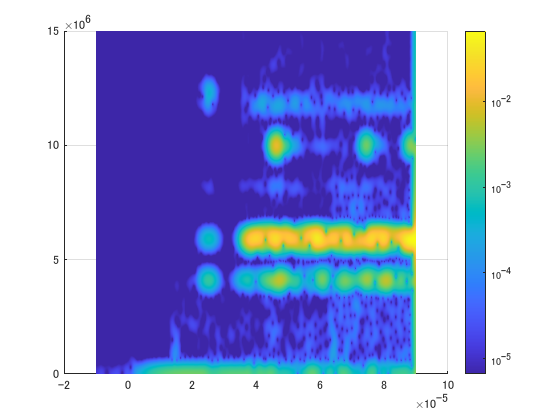

[T,F] = meshgrid(t,f);
surf(T,F,s,EdgeColor="none");
set(gca,'ColorScale','log')
colorbar
xlabel('Time')

ylabel('Frequency')
view(2);

### 簡易的な結果の確認

`stft`はオプション`Display`を指定するか，あるいは出力引数を取らない事により，画面へ結果を出力します．

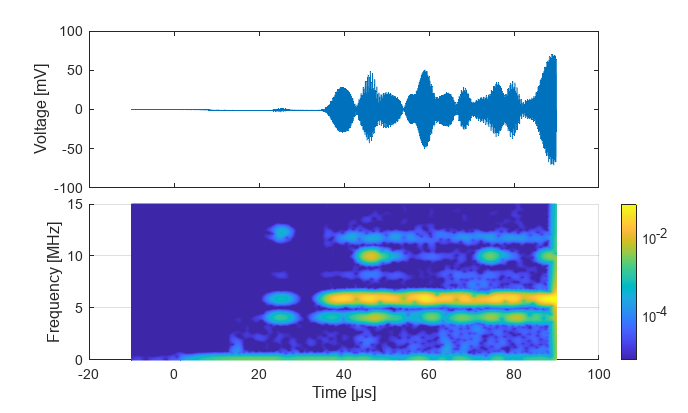

load('test_data\data20231127-113905-trimed.mat'); %timevec
waveform = waveform1and2;

windowWidth = 2e-6;
maxF = 15e6;
common.stft(waveform, timevec, windowWidth, maxF);

## 入力引数

#### waveform  --- 解析対象の時間信号

数値ベクトル，時間的な信号（波形）を一般には与えます．

複素数ベクトルも受けることができますが，stftでは振幅のみをsとして返します．

#### timevec  --- 時間信号に対応した時間軸

実数ベクトル．waveformの時間軸

#### windowWidth --- 窓関数の時間長さ

`(timevec(end)-timevec(1))/100`（既定値）

実数スカラー．解析に用いる窓関数の時間幅を与えます．窓関数の片側の長さではなく，窓関数全体の幅であることに注意してください．

#### maxF --- 解析対象の最大周波数

実数スカラー．解析対象の最大周波数を与えます．与えない場合でも，全周波数範囲の解析になります．が，plotのコストが高いため，最大周波数は設定することをおすすめします．

### 名前と値の引数

オプションの引数のペアを Name1=Value1,...,NameN=ValueN として指定します。ここで、Name は引数名で、Value は対応する値です。名前と値の引数は他の引数の後に指定しなければなりませんが、ペアの順序は重要ではありません。

#### Window -- 窓関数

common.gauss(1.0) (既定値) | "hann" | "rect" | function_handle

窓関数形状を指定します．文字列で'hann', 'rect'のように関数名を指定するか，規格化された窓関数の関数ハンドルを渡してください．利用可能なウィンドウのリストは別途参照して下さい．MatlabのSignal Processing Toolsが提供するウィンドウは使えませんので，注意ください．

#### DivT -- stftの結果の時間方向の刻み

400（既定値） | double

stftでは時間方向に窓関数をシフトしながらFFTを行いますが，このシフトの幅を決める値です．たとえば800を指定するとより細かいSTFT結果が得られます．

#### DivF -- stftの結果の周波数方向の刻み

400（既定値） | double

sの周波数方向の刻みの最小値を指定するパラメータです．特にmaxFが指定されている場合，maxFまでの周波数を最低でもDivFに分割するように適当に入力信号ベクトルに0を追加します．maxF, DivFに過度に大きい値を指定すると解析時間が膨大になる可能性があります．

#### Display -- stftの結果の表示

"off"（既定値） | "on" | logical

"on"を指定した場合，出力引数を設定せずにstft( ___ )を使用した場合と同様に，結果を現在のFigureウィンドウに表示します．

## 出力引数

#### s --- STFT結果

実数行列．各列が異なる時間に対応し，対応する時刻を中心とした領域のフーリエ変換の結果を示す．結果は振幅（絶対値）を返し，複素数ではない．

#### f --- sの周波数軸

実数ベクトル

#### t --- sの時間軸

実数ベクトル

## アルゴリズム

## 参照

[commonライブラリ](matlab:open('./common_reference.mlx'))